QEA II Final 

Key objective: Take the frequency and find the notes that are being played.

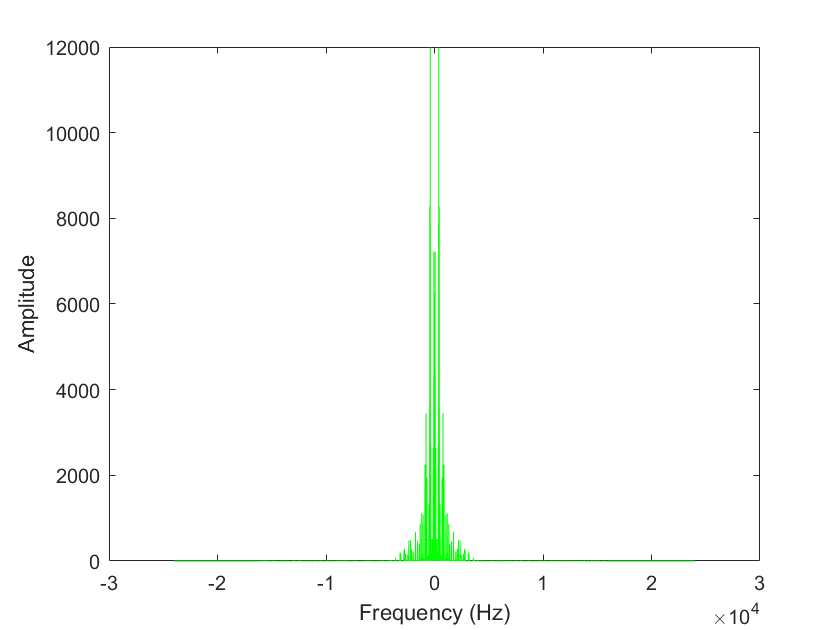

[x, Fs] = audioread("mary’s lamb.wav");
sound(x, Fs);

N = length(x);
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);

X = fft(x);
spectrum = fftshift(X);

%frequency vs. amplitude
plot(f,fftshift(abs(X)),'g');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

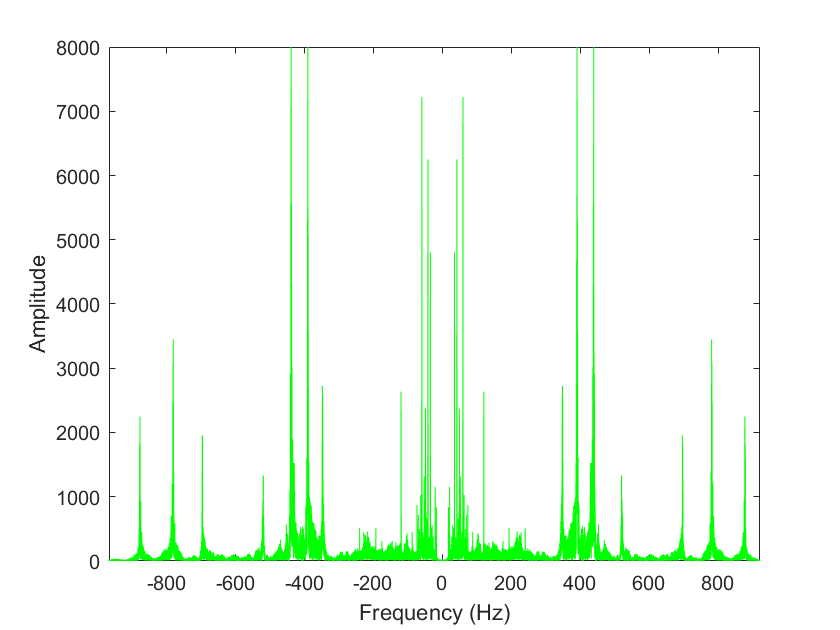


plot(f,fftshift(abs(X)),'g');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([-967 921])
ylim([0 8000])

Plotting the frequency vs. amplitude tells us the frequency which corrolates to a specific note being played on the piano.

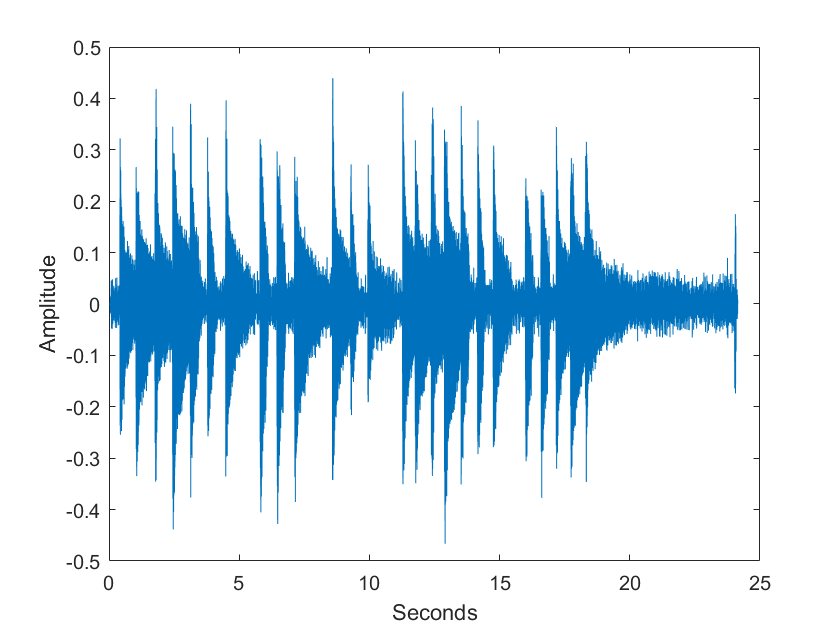

%going back to amplitude over time 
y = x;
y = y(:,1);
    dt = 1/Fs;
    t = 0:dt:(length(y)*dt)-dt;
    plot(t,y); xlabel('Seconds'); ylabel('Amplitude');

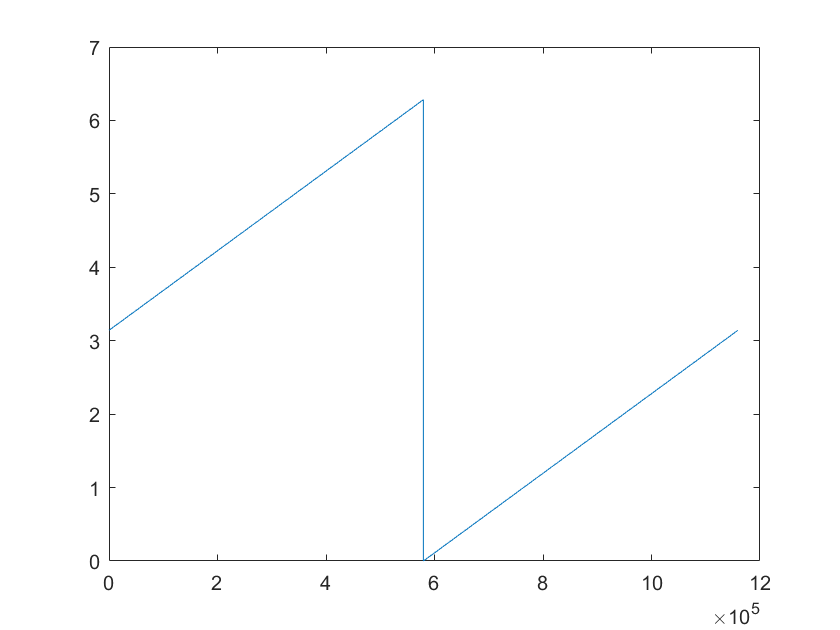

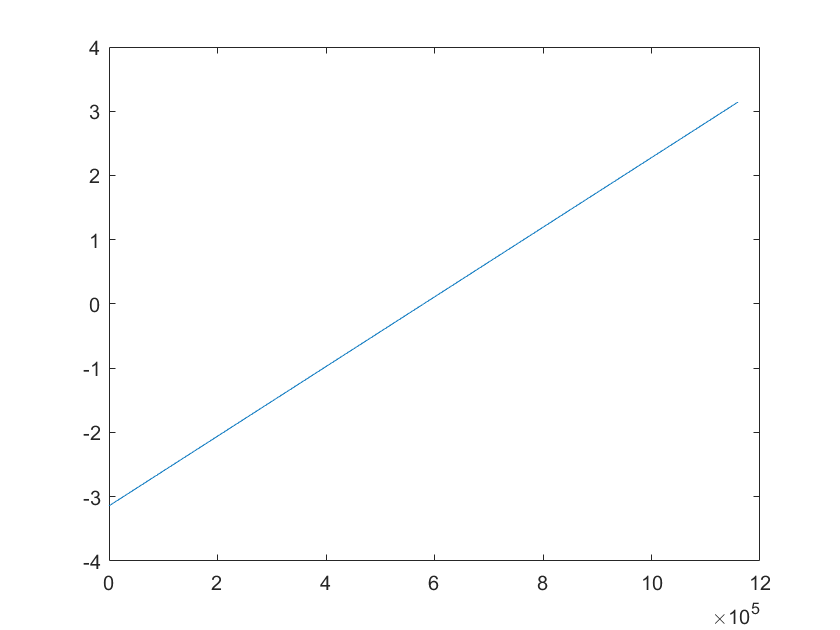

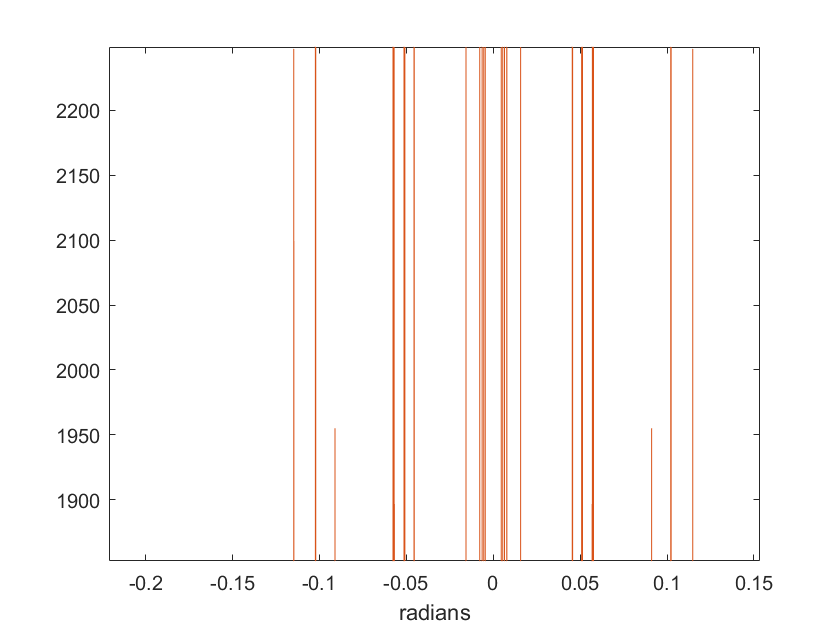

    figure   

%Reading from microphone for continuous cft


%Filtering the input
% filter_inds = -Fs*pi <= f & f <= -Fs*pi/2 | Fs*pi/2 <= f & f <= Fs*pi;
% spectrum_filt = spectrum;
% spectrum_filt(filter_inds) = spectrum_filt(filter_inds)/10;
% 
% yfilt = real(ifft(ifftshift(spectrum_filt)));
% plot(f,fftshift(spectrum_filt),'r');
% xlabel('Frequency (Hz)');
% ylabel('Amplitude');

%idk 
filtered_amp = [];
Fs_t = Fs*2*pi;
y_t = abs(fftshift(fft(y)));

for i = 1:length(y)
    f = y_t(i);
    if (i < -Fs_t/2) & (i > -Fs_t/4)
        filtered_amp(i) = f/10;
    elseif (f < Fs_t/2) & (f > Fs_t/4)
        filtered_amp(i) = f/10;
    else
        filtered_amp(i) = f;
    end

end

%raw spectrum
plot(f, y_t);
h = xlabel('Frequency (rad/s)');
set(h, 'FontSize',20);
h = ylabel('Amplitude');
set(h, 'FontSize',20);
title("Raw Spectrum")

%filtered spectrum
plot(f, filtered_amp);
h = xlabel('Frequency (rad/s)');
set(h, 'FontSize',20);
h = ylabel('Amplitude');
set(h, 'FontSize',20);
title("Filtered Spectrum")